# State Signal Selection Test File

**Author: Nina Matthews**

**Project: Masters Dissertation - Hierarchical portfolio stress-testing with flexible probabilities**

**Last edit: 25/08/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

#### **Test Data: **ASSET Log Dif Returns

"DATA-PROCESSED-INVARIANT-LOGDIF_RETURNS-M-TTABLE-20070731-20230228.mat"

## **Purpose**

**This file runs a 'classic' backtest where the mean and varaince input to optimizations are ****historical mean and variance.**

#### **Note on file and class structures:**

Here the **benchmark functions** (methods) are stored separately to the **backtesting functions** (methods) as we can later make the benchmark class a subclass to the backtesting class. We can also have the **hrp functions** (methods) as a subclass of the benchmark class as it houses its own specialised functions but is used as a benchmark portfolio optimization. 

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path to **backtest** function folder

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/backtest/functions/'));

Set path to **benchmark** function folder *(Later the benchmark class can become a deriviative class to the backtest class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/benchmarks/functions/'));

Set path to **HRP** function folder *(Later the benchmark class can become a deriviative class to the benchmark class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hrp/functions/'));
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hsfp/functions/'));

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/'));
% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Backtesting/',exportName);

Set Output data EXPORT path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/', exportName);

## 2. Load Test Data: ASSET Log Dif Returns & Sig Data

fileName = 'DATA-PROCESSED-ASSETCL_INVARIANT-RETURNS-M-TTABLE-20070731-20230228.mat';
load(fileName)
fileName = 'DATA-PROCESSED-SIG-ADJUSTED-SMTH-3M3Y_NORM-M-TTABLE-20070531-20230228.mat';
load(fileName)

% Find the minimum value and its index in the JIBA3M column
[minValue, minIndex] = min(M_Ret_TT.Cash);

% Get the date corresponding to the minimum value
minDate = M_Ret_TT.Time(minIndex);

2.1 Create ASSETCL plot names (excludes the underscore)

% rename the variables with underscores instead of spaces
BALFUN_PlotNames = strrep(M_Ret_TT.Properties.VariableNames, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
BALFUN_PlotNames = strrep(BALFUN_PlotNames, 'TR', '');

## Test for removing cash: will comment out extra lines in functions to accomodate no cash.. to reverse later

% M_Ret_TT = removevars(M_Ret_TT, 'Cash');

# 3. Backtest Model Variations 

% Options:   - none (default) 

%            - rolling_w

%            - exp_decay

%            - crisp

%            - kernel

%            - e_pooling

%            - ew_ensemble

%            - cb_ensemble

Window_len = 12;
tau = 12;
alpha = 0.1;
z_target = 'latest';
gamma = 2;
h = 0.5;
ensemble_wt_method = 'log-linear';
%%%%% ********** Problem lies with EPool_prior when going into BT as it
%%%%%%  depends on size of sig_data... need to integrate into BT or into the ep_probs.m function itself....
%%% Therefore, cannot currently test ep, ew_ensemble or cb_ensemble until
%%% ep is resolved.
tau_prior = 1*12; % Ann did 5 yrs


% Rfr = mean(M_Ret_TT.Cash);
hsfp_parameters = struct('window',[],'tau',[],'alpha',[],'z_target',[], ...
    'gamma',[],'h',[], 'tau_prior',[],'ensemble_wt_method',[]);
hsfp_parameters.window = Window_len;
hsfp_parameters.tau = tau;
hsfp_parameters.alpha = alpha;
hsfp_parameters.z_target = z_target;
hsfp_parameters.gamma = gamma;
hsfp_parameters.h = h;
hsfp_parameters.tau_prior = tau_prior;
hsfp_parameters.ensemble_wt_method = ensemble_wt_method;


backtest_object = struct('returns',[],'signals',[],'method',[], 'parameters',[]);
backtest_object.returns = M_Ret_TT;
% Ensemble needs more than 1 signal series
backtest_object.signals = timetable(SIG_SMOOTHED_TT.Time, ...
    SIG_SMOOTHED_TT.lagged_SAMYM3Y_Index, SIG_SMOOTHED_TT.SAVIT40_Index);
% NB: needs to be a timetable object
backtest_object.method = 'none';
backtest_object.parameters = hsfp_parameters; 

backtest_object = struct with fields:
       returns: [189×6 timetable]
       signals: [189×2 timetable]
        method: 'none'
    parameters: [1×1 struct]



% Test backtest moment calculation
% [hsfp_mu, hsfp_cov,p] = backtest_moments(backtest_object);

#### 3.1 Call the backtest_function

Window = 36;
[Rolling_portfolioSet,Realised_tsPIndx,Realised_tsPRet,Opt_tsWts] = backtest_analysis(backtest_object, Window);

figure('InnerPosition', [100, 100, 600, 600]);

colours = [[0, 0, 0.5];           % blue
    0.8500 0.3250 0.0980;  % orange
    0.9290 0.6940 0.1250;  % yellow,
    0.4940 0.1840 0.5560;  % purple
    0.4660 0.6740 0.1880;  % green
    0.3010 0.7450 0.9330;  % light blue
    0.6350 0.0780 0.1840;  % red
    0.9290 0.6940 0.6940]; % new color (light pink)

numLines = size(Rolling_portfolioSet, 2);
for i = 1:numLines
    lineColor = colours(mod(i-1, size(colours, 1))+1, :);
    plot(Rolling_portfolioSet.Time, Rolling_portfolioSet{:, i}, 'LineWidth', 1.2, 'Color', lineColor);
    hold on;
end

ylabel('Price Index', 'FontSize', 15);
xlabel('Time', 'FontSize', 15);
title(['Non-HSFP Backtest: TRIs Based on a ', num2str(Window), ' Month Rolling Window'], 'FontSize', 16);
legend(Rolling_portfolioSet.Properties.VariableNames, 'Location', 'northwest', 'FontSize', 14);
set(gca, 'FontSize', 12);
UnAdj_36RollW_Output_Plot = gcf;
hold off;

legend("Position", [0.17173,0.5673,0.36486,0.2424])

legend("Position", [0.1896,0.58723,0.36979,0.2424])

**Export Unconstrained Traditional Optimal Portfolio Performance Plot**

exportName = 'UnAdj_36RollW_Output_Plot.pdf';
exportgraphics(UnAdj_36RollW_Output_Plot,fullfile(imageExportpath,exportName),'Resolution',300);

3D portfolio weight surface area plots

Z = [Opt_tsWts{2,2}];
Y = Rolling_portfolioSet.Time;
ribbon(Y,Z,0.5)

title(['Optimal Weight Surfaces for ' Opt_tsWts{1,2} ' Portfolio'],'FontSize', 16 )
colours = [0 0.4470 0.7410; % dark blue
    0.8500 0.3250 0.0980; % orange
    0.9290 0.6940 0.1250; % yellow
    0.4940 0.1840 0.5560; % purple
    0.3010 0.7450 0.9330]; % light blue
colormap(colours)
xlabel('Asset Class')
set(gca,'xtick',1:5,'xticklabel',{'ALB Index','FINI15 Index','INDI25 Index','RESI20 Index','Cash'});
ylabel('Time')
zlabel('Opt Weight')

view([57.336 78.226])

Y = Rolling_portfolioSet.Time;
Z = [Opt_tsWts{2,2}];
h = ribbon(Y,Z,0.5);
title('Optimal Weight Surfaces for MV-SR Portfolio','FontSize', 16 )
colours = [0 0.4470 0.7410; % dark blue
    0.8500 0.3250 0.0980; % orange
    0.9290 0.6940 0.1250; % yellow
    0.4940 0.1840 0.5560; % purple
    0.3010 0.7450 0.9330]; % light blue
colormap(colours)
h(1).EdgeColor = "white";
h(2).EdgeColor = "white";
h(3).EdgeColor = "white";
h(4).EdgeColor = "white";
h(5).EdgeColor = "white";
xlabel('Asset Class')
set(gca,'xtick',1:5,'xticklabel',{'ALB Index','FINI15 Index','INDI25 Index','RESI20 Index','Cash'});
ylabel('Time')
zlabel('Opt Weight')
view([57.336 78.226])

**Export Optimal Weight Surface Plot**

exportName = 'wts_surface_NoneHSFP_MV.pdf';
exportgraphics(h,fullfile(imageExportpath,exportName),'Resolution',300);

% Set Y axis for datetime object
Y = Rolling_portfolioSet.Time;
% Create fig
% f1 = figure('OuterPosition', [100, 100, 600, 600]);
sgtitle(['Non-HSFP Backtest: ', num2str(Window), ' Month Rolling Window'], 'FontSize', 13);
% plot grid
numRows = 2;
numCols = 3;

% Colour palette: Hexadecimal Colour Codes
colours = [0 0.4470 0.7410; % dark blue
    0.8500 0.3250 0.0980; % orange
    0.9290 0.6940 0.1250; % yellow
    0.4940 0.1840 0.5560; % purple
    0.3010 0.7450 0.9330]; % light blue


% Colour palette: Hexadecimal Colour Codes
BF_colours = [0.4660 0.6740 0.1880; % green
     0.3010 0.7450 0.9330; % light blue
   0 0.4470 0.7410]; % dark blue

%%% 1. Equally Weighted %%%%
ax(1) = subplot(numRows, numCols, 1);
grid on
Z = [Opt_tsWts{2,1}];
h = ribbon(Y,Z,0.5);
colormap(ax(1),colours);
for i = 1:numel(h)
    h(i).EdgeColor = colours(i,:);
end
xlabel('Asset Class')
set(gca,'xtick',1:5,'xticklabel',{'ALBI','FINI15','INDI25','RESI20','Cash'});
ylabel('Time')
zlabel('Opt Weight')
view([56.7207012835473 33.9084446444713]);
title(['Non-HSFP: ' Opt_tsWts{1,1} ' Portfolio Controls'],'FontSize', 9);


%%% 2.  MV SR Max %%%%
ax(2) = subplot(numRows, numCols, 2);
Z = [Opt_tsWts{2,2}];
grid on
h1 = ribbon(Y,Z,0.5);
colormap(ax(2),colours);
for i = 1:numel(h1)
    h1(i).EdgeColor = colours(i,:);
end
xlabel('Asset Class')
set(gca,'xtick',1:5,'xticklabel',{'ALBI','FINI15','INDI25','RESI20','Cash'});
ylabel('Time')
zlabel('Opt Weight')
view([57.336 78.226])
title(['Non-HSFP: ' Opt_tsWts{1,2} ' Portfolio Controls'],'FontSize', 9);


%%% 3. BF B-H %%%%
ax(3) = subplot(numRows, numCols, 3);
Z = [Opt_tsWts{2,3}];
h2 = ribbon(Y,Z,0.5);
colormap(ax(3),BF_colours);
for i = 1:numel(h2)
    h2(i).EdgeColor = BF_colours(i,:);
end
xlabel('Asset Class')
set(gca,'xtick',1:3,'xticklabel',{'ALSI', 'Cash','ALBI'});
ylabel('Time')
zlabel('Opt Weight')
view([60.3745064177363 23.430953351469])
title(['Non-HSFP: ' Opt_tsWts{1,3} ' Portfolio Controls'],'FontSize', 9);

%%% 4. HRP %%%%
ax(4) = subplot(numRows, numCols, 4);
Z = [Opt_tsWts{2,4}];
h3 = ribbon(Y,Z,0.5);
colormap(ax(4),colours);
for i = 1:numel(h3)
    h3(i).EdgeColor = colours(i,:);
end
xlabel('Asset Class')
set(gca,'xtick',1:5,'xticklabel',{'ALBI','FINI15','INDI25','RESI20','Cash'});
ylabel('Time')
zlabel('Opt Weight')
view([61.2860583430572 42.5455046439628])
title(['Non-HSFP: ' Opt_tsWts{1,4} ' Portfolio Controls'],'FontSize', 9);

%%% 5. BF CM %%%%
ax(5) = subplot(numRows, numCols, 5);
Z = [Opt_tsWts{2,5}];
h4 = ribbon(Y,Z,0.5);
colormap(ax(5),BF_colours);
for i = 1:numel(h4)
    h4(i).EdgeColor = BF_colours(i,:);
end
xlabel('Asset Class')
set(gca,'xtick',1:3,'xticklabel',{'ALSI', 'Cash','ALBI'});
ylabel('Time')
zlabel('Opt Weight')
view([53.0820910151692 23.4309538458165])
title(['Non-HSFP: ' Opt_tsWts{1,5} ' Portfolio Controls'],'FontSize', 9);

%%% 6. Performance Plot %%%%
subplot(numRows, numCols, 6);
axis square;
perform_colours = [[0, 0, 0.5];           % blue
    0.8500 0.3250 0.0980;  % orange
    0.9290 0.6940 0.1250;  % yellow,
    0.4940 0.1840 0.5560;  % purple
    0.4660 0.6740 0.1880;  % green
    0.3010 0.7450 0.9330;  % light blue
    0.6350 0.0780 0.1840;  % red
    0.9290 0.6940 0.6940]; % new color (light pink)

numLines = size(Rolling_portfolioSet, 2);
for i = 1:numLines
    lineColor = perform_colours(mod(i-1, size(perform_colours, 1))+1, :);
    plot(Rolling_portfolioSet.Time, Rolling_portfolioSet{:, i}, 'LineWidth', 1.2, 'Color', lineColor);
    hold on;
end

ylabel('Price Index', 'FontSize', 9);
xlabel('Time', 'FontSize', 15);
% ylim([0.9, 4.5])
title('Non-HSFP: Portfolio Cummulative TRIs', 'FontSize', 9);
legend(Rolling_portfolioSet.Properties.VariableNames, 'Location', 'northwest', 'FontSize', 6);
set(gca, 'FontSize', 9);

UnAdj_36RollW_Output_Plot = gcf;
hold off;




% Export the fig as a PDF
UnAdj_RollW_Wt_Surfaces_Plot = gcf;
hold off

% subplot(2,3,1)
% view([58.18 17.39])
% subplot(2,3,2)
% view([69.23 58.45])
% subplot(2,3,4)
% view([60.95 25.20])


**Export Unconstrained Traditional Optimal Weight Surface Plot**

exportName = 'UnAdj_RollW_Wt_Surfaces_Plot.pdf';
exportgraphics(UnAdj_RollW_Wt_Surfaces_Plot,fullfile(imageExportpath,exportName),'Resolution',300);

## 4. Calculation of Portfolio Performance Measures 

**Return Measures**

- Annualised returns

- Annualised volatility

- Annualised Sharpe Ratio

**Risk Measures**

- CVaR

- Max Drawdown

GRet_EW = Realised_tsPRet{1,1};
exportName = 'test_annual_returns_EW_PRet';
writematrix(GRet_EW,fullfile(dataExportpath,exportName));

### 4.1 Annualised Returns

Geometric average or annualised return


$$ $\quad r_G=\left(\prod_{i=1}^n\left(1+r_i\right)\right)^{\frac{f}{n}}-1$
$$


where: n the number of periods under analysis

f the number of periods within the year (monthly f 12, quarterly f 4).

*(Test case Rolling Window using SA Money Supply with window length of 12 months in a 36 month rolling window backtest.)*

AnnPRet = zeros(1,length(Realised_tsPRet));
f = 12; % Number of periods within a year (e.g., 12 for monthly)

for port = 1: length(Realised_tsPRet)

    PRet = Realised_tsPRet{2,port};
    % Number of periods under analysis
    n = height(PRet);
    % Calculate the geometric mean return (in decimals)
    AnnPRet(port) = ((prod(1 + PRet))^ (f / n)) - 1;

AnnPRet =     0.1044    0.0726    0.1087    0.0583    0.1083    0.1229    0.0842    0.0582


end

i_monthly_percent = 4.5211

AnnPRet
i_monthly_percent = ((1 + 0.7).^(1/12) - 1)*100

#### PRet cell array to TT

% Initialize an empty cell array to store timetables
timetables = cell(1, length(Realised_tsPRet));

% Loop through each cell in the cell array
for i = 1:length(Realised_tsPRet)
    data = Realised_tsPRet{2, i};  % Get the data from the cell
    variableName = Realised_tsPRet{1, i};  % Use the name from the first row of Realised_tsPRet
    
    % Store the data in the cell array
    timetables{i} = data;  
end

% Create a timetable from the cell array, assuming timeVector is your actual time data
timeVector = Rolling_portfolioSet.Time;
PRet_TT = timetable(timeVector, timetables{:}, 'VariableNames', Realised_tsPRet(1, :));

#### OptWts cell array to TT

% Initialize an empty cell array to store timetables
timetables = cell(1, length(Opt_tsWts));

% Loop through each cell in the cell array
for i = 1:length(Opt_tsWts)
    data = Opt_tsWts{2, i};  % Get the data from the cell
    variableName = Opt_tsWts{1, i};  % Use the name from the first row of Realised_tsPRet
    
    % Store the data in the cell array
    timetables{i} = data;  
end

% Create a timetable from the cell array, assuming timeVector is your actual time data
timeVector = Rolling_portfolioSet.Time;
OptWts_TT = timetable(timeVector, timetables{:}, 'VariableNames', Opt_tsWts(1, :));

OptWts_array = table2array(OptWts_TT);

### 4.2 Annualised Volatility

Test case Rolling Window using SA Money Supply with window length of 12 months in a 36 month rolling window backtest

AnnPRisk = zeros(1,length(Realised_tsPRet));

for port = 1: length(Realised_tsPRet)

    AnnPRisk(port) = sqrt(12)*sqrt(var(Realised_tsPRet{2,port}));

AnnPRisk =     0.0967    0.0879    0.0997    0.0035    0.0949    0.1385    0.0760    0.0035


end

AnnPRisk

PMean = zeros(1,length(Realised_tsPRet));

for port = 1: length(Realised_tsPRet)

    PMean(port) = mean(Realised_tsPRet{2,port});
end

PVar = zeros(1,length(Realised_tsPRet));
for port = 1: length(Realised_tsPRet)

    PVar(port) = sqrt(var(Realised_tsPRet{2,port}));
end

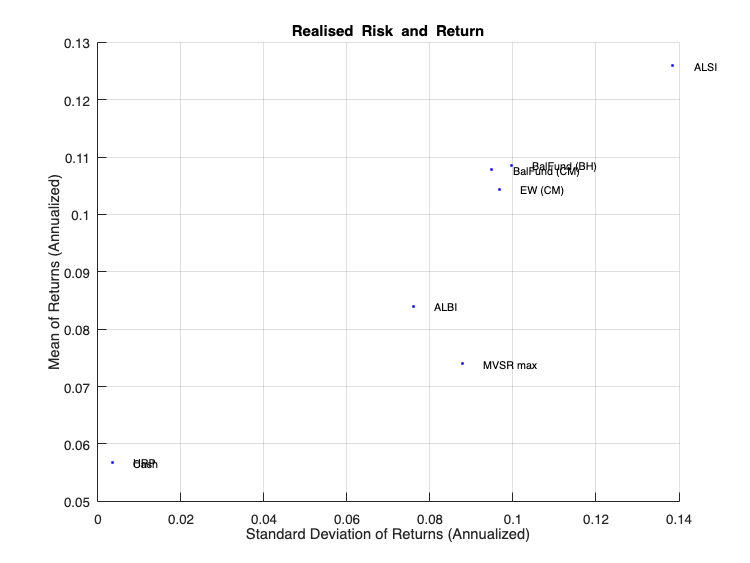

Sigma = cov(Returns2)

% scatter(AnnPRet,AnnPRisk,Rolling_portfolioSet.Properties.VariableNames);
clf;portfolioexamples_plot('Realised Risk and Return', ...
    {'scatter',sqrt(diag(PRetCovar)),PMean', Rolling_portfolioSet.Properties.VariableNames, '.b'});

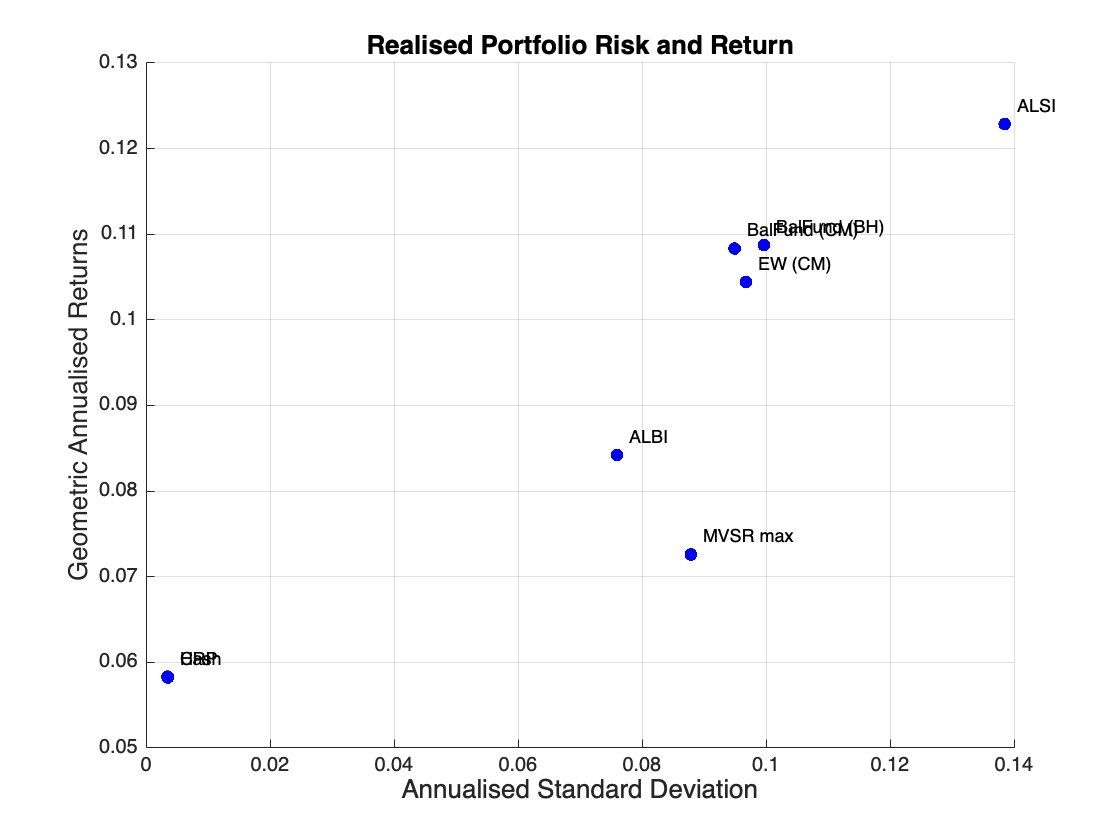

scatter(AnnPRisk,AnnPRet, 300, '.b')
ylabel('Geometric Annualised Returns', 'FontSize', 13)
xlabel('Annualised Standard Deviation', 'FontSize', 13)
title('Realised Portfolio Risk and Return', 'FontSize', 13)

% make data labels:
text((AnnPRisk+0.002),AnnPRet+0.002,{'EW (CM)', 'MVSR max', 'BalFund (BH)', 'HRP', 'BalFund (CM)', 'ALSI', 'ALBI', 'Cash'}, 'FontSize', 9)
grid on
NonHSFP_RealisedAnnRisk_Return_scatter = gcf;

**Export Unconstrained Traditional Optimal Weight Surface Plot**

exportName = 'NonHSFP_RealisedAnnRisk_Return_scatter.pdf';
exportgraphics(NonHSFP_RealisedAnnRisk_Return_scatter,fullfile(imageExportpath,exportName),'Resolution',300);